# **Bayesian Optimisation Example**

**SECTION 1.0**

Goal: *maximise the function f(x) = x.*sin( x );  in the interval [0, 10]*

clear
close all
x = linspace( 0, 10, 501 ).';
f = x.*sin( x );


Extract 7 points for training an initial surrogate model & plot the results:

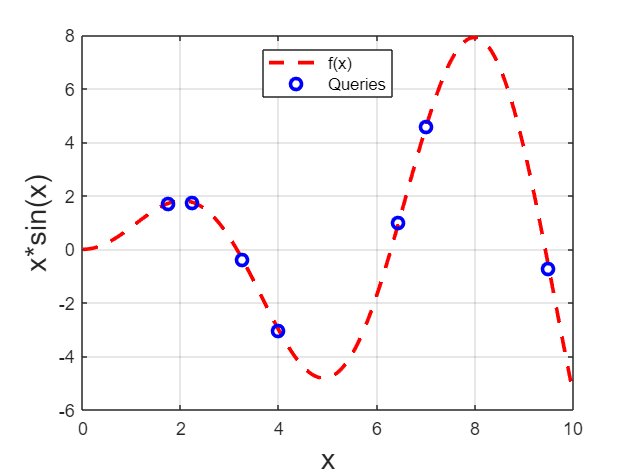

X = [ 9.5, 2.24, 4, 1.76, 3.26, 6.44, 7.0 ].';
Y = X .* sin( X );
plot( x, f, 'r--', X, Y, 'bo', 'LineWidth', 2 );
grid on
xlabel( "x", "FontSize", 16 );
ylabel( "x*sin(x)", "FontSize", 16 );
legend( "f(x)", "Queries", "Location", "north")

**SECTION 2.0**

Create the Bayesian Optimisation object. Assume a Gaussian Process Regression model and the Upper Confidence Bound acquisition function

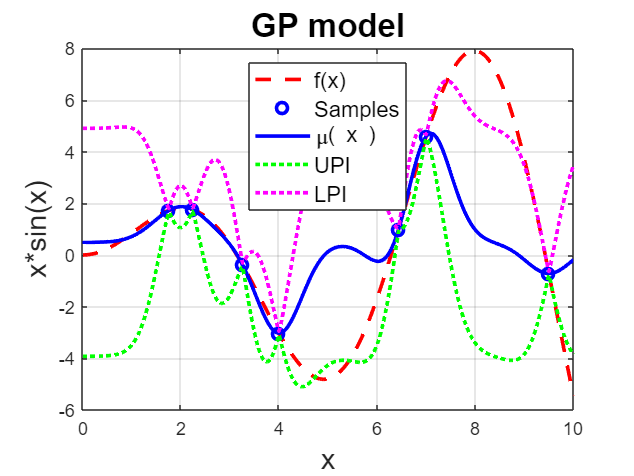

B = bayesOpt( "gpr", "aei");
B = B.conDataCoding( 0, 10 );
B = B.setProblemTypeState( "Maximisation" );
B = B.setTrainingData( X, Y );
[ Yp, ~, Yint] = B.predict( x, 0.05 );
close all
figure;
plot(x, f, 'r--', B.X, B.Y, 'bo', x, Yp, 'b-', 'LineWidth', 2);
grid on
legend( "f(x)", "Samples", "\mu( x )", 'Location', 'north', "FontSize", 12 );
xlabel( "x", "FontSize", 16 );
ylabel( "x*sin(x)", "FontSize", 16 );
title( "GP model", "FontSize", 18 );
hold on;
plot(  x, Yint( :,1 ), 'g:', x, Yint( :,2 ), 'm:', 'LineWidth', 2);
legend( "f(x)", "Samples", "\mu( x )", "UPI", "LPI", 'Location', 'north', "FontSize", 12 );

**SECTION 3.0**

Maximise the acquisition function

B = B.acqFcnMaxTemplate();

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       2   -1.510724e-02    0.000e+00    2.526e+00
    1       6   -1.008985e-01    0.000e+00    1.268e+01    7.463e-02
    2       8   -1.609010e-01    0.000e+00    5.006e+00    1.437e-02
    3      12   -3.213344e-01    0.000e+00    1.040e+00    3.265e-02
    4      16   -3.221946e-01    0.000e+00    4.920e-01    2.762e-03
    5      18   -3.223931e-01    0.000e+00    1.000e-01    5.310e-04
    6      20   -3.224238e-01    0.000e+00    2.007e-02    2.437e-04
    7      22   -3.224257e-01    0.000e+00    4.818e-04    7.736e-05
    8      24   -3.224257e-01    0.000e+00    2.000e-04    8.082e-07
    9      26   -3.224257e-01    0.000e+00    2.001e-06    7.221e-07
   10      28   -3.224257e-01    0.000e+00    2.130e-07    7.585e-09

Local minimum found that satisfies the cons

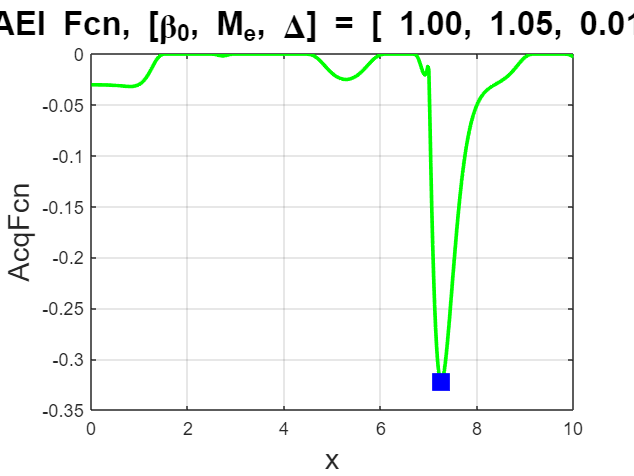

U = B.AcqObj;
figure;
A = U.evalFcn( x, false, U.Beta );
plot( x, A, 'g-', 'LineWidth', 2); grid on
xlabel( "x", "FontSize", 16 )
ylabel( "AcqFcn", "FontSize", 16 )
switch B.AcqFcn
    case "ucb"
        Tstr = sprintf( "UCB Fcn, \\beta = %4.3f", U.Beta );
    case "ei"
        Tstr = sprintf( "EI Fcn, \\beta = %4.3f", U.Beta );
    otherwise
        Tstr = sprintf( "AEI Fcn, [\\beta_0, M_e, \\Delta] = [ %3.2f, %3.2f, %4.3f]",...
            B.HyperPar);
end
title( Tstr, "FontSize", 18 ); 
hold on, plot( B.Xnext, B.AcqObj.evalFcn( B.Xnext ), "bs", "MarkerSize", 12, "MarkerFaceColor", "blue" );
grid on
hold off

**SECTION 4.0**

Query f(x) at the suggested value and update the GP model

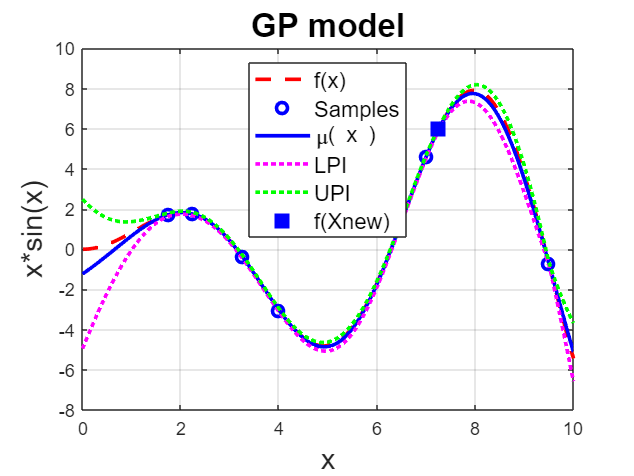

figure;
Xnew = B.Xnext;
Ynew = Xnew * sin( Xnew );
B = B.addNewQuery( Xnew, Ynew );
[ Yp, ~, Yint ] = B.predict( x );
plot(x, f, 'r--', B.X, B.Y, 'bo', x, Yp, 'b-', x, Yint( :,1 ), 'm:',...
    x, Yint( :,2 ), 'g:',  'LineWidth', 2);
hold on
plot( Xnew, Ynew, 'bs', 'MarkerSize', 10, 'MarkerFaceColor', 'blue');
grid on
legend( "f(x)", "Samples", "\mu( x )", "LPI", "UPI", "f(Xnew)", 'Location', 'north', "FontSize", 12 );
xlabel( "x", "FontSize", 16 );
ylabel( "x*sin(x)", "FontSize", 16 );
title( "GP model", "FontSize", 18 );

**SECTION 5.0**

Iteration 2. Now re-optimise the acquisition function and add the new query to the training data and retrain the surrogate model.

B = B.acqFcnMaxTemplate();

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       2   -1.793596e-02    0.000e+00    6.284e-02
    1      15   -1.793712e-02    0.000e+00    1.087e-02    3.264e-04
    2      17   -1.794169e-02    0.000e+00    1.007e-03    1.442e-04
    3      19   -1.794170e-02    0.000e+00    2.944e-05    9.612e-06
    4      22   -1.794170e-02    0.000e+00    5.078e-05    3.746e-08
    5      29   -1.794170e-02    0.000e+00    1.261e-06    3.746e-08

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of th

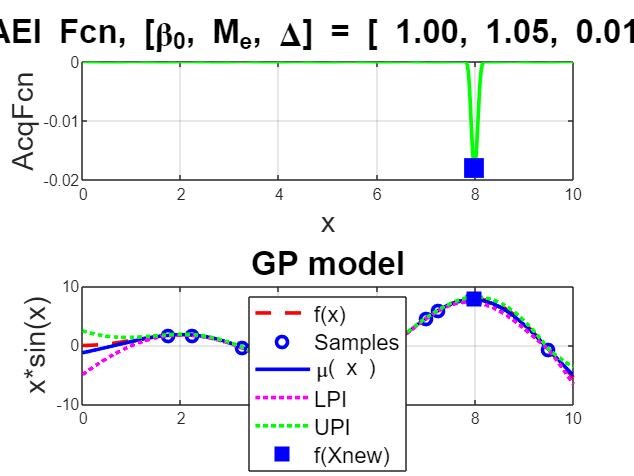

figure;
Xnew = B.Xnext;
subplot(2,1,1), plot( x, B.AcqObj.evalFcn( x ), 'g-', Xnew, B.AcqObj.evalFcn( Xnew ), 'bs', 'MarkerSize', 12,'LineWidth', 2, 'MarkerFaceColor','blue');
grid on
xlabel( "x", "FontSize", 16 )
ylabel( "AcqFcn", "FontSize", 16 )
switch B.AcqFcn
    case "ucb"
        Tstr = sprintf( "UCB Fcn, \\beta = %4.3f", U.Beta );
    case "ei"
        Tstr = sprintf( "EI Fcn, \\beta = %4.3f", U.Beta );
    otherwise
        Tstr = sprintf( "AEI Fcn, [\\beta_0, M_e, \\Delta] = [ %3.2f, %3.2f, %4.3f]",...
            B.HyperPar);
end
title( Tstr, "FontSize", 18 ); 
subplot(2,1,2)
Xnew = B.Xnext;
Ynew = Xnew * sin( Xnew );
B = B.addNewQuery( Xnew, Ynew );
plot(x, f, 'r--', B.X, B.Y, 'bo', x, Yp, 'b-', x, Yint( :,1 ), 'm:',...
    x, Yint( :,2 ), 'g:',  'LineWidth', 2);
hold on
plot( Xnew, Ynew, 'bs', 'MarkerSize', 10, 'MarkerFaceColor', 'blue');
grid on
legend( "f(x)", "Samples", "\mu( x )", "LPI", "UPI", "f(Xnew)", 'Location', 'north', "FontSize", 12 );
xlabel( "x", "FontSize", 16 );
ylabel( "x*sin(x)", "FontSize", 16 );
title( "GP model", "FontSize", 18 );